## **Driver test program to check Clothoids library**

**Test G1 clothoid**

-------------------
TEST N.1


Error initial point 0 0


Error final point   1.11022e-15 8.88178e-16


Iterations 3


-------------------
TEST N.2


Error initial point 0 0


Error final point   0 2.98736e-16


Iterations 3


-------------------
TEST N.3


Error initial point 0 0


Error final point   0 -7.6246e-16


Iterations 3


-------------------
TEST N.4


Error initial point 0 0


Error final point   -3.10862e-15 3.41686e-16


Iterations 3


-------------------
TEST N.5


Error initial point 0 0


Error final point   -2.22045e-15 -2.44249e-15


Iterations 3


-------------------
TEST N.6


Error initial point 0 0


Error final point   -4.44089e-16 4.44089e-16


Iterations 3


-------------------
TEST N.7


Error initial point 0 0


Error final point   0 3.13475e-21


Iterations 2


-------------------
TEST N.8


Error initial point 0 0


Error final point   0 0


Iterations 2


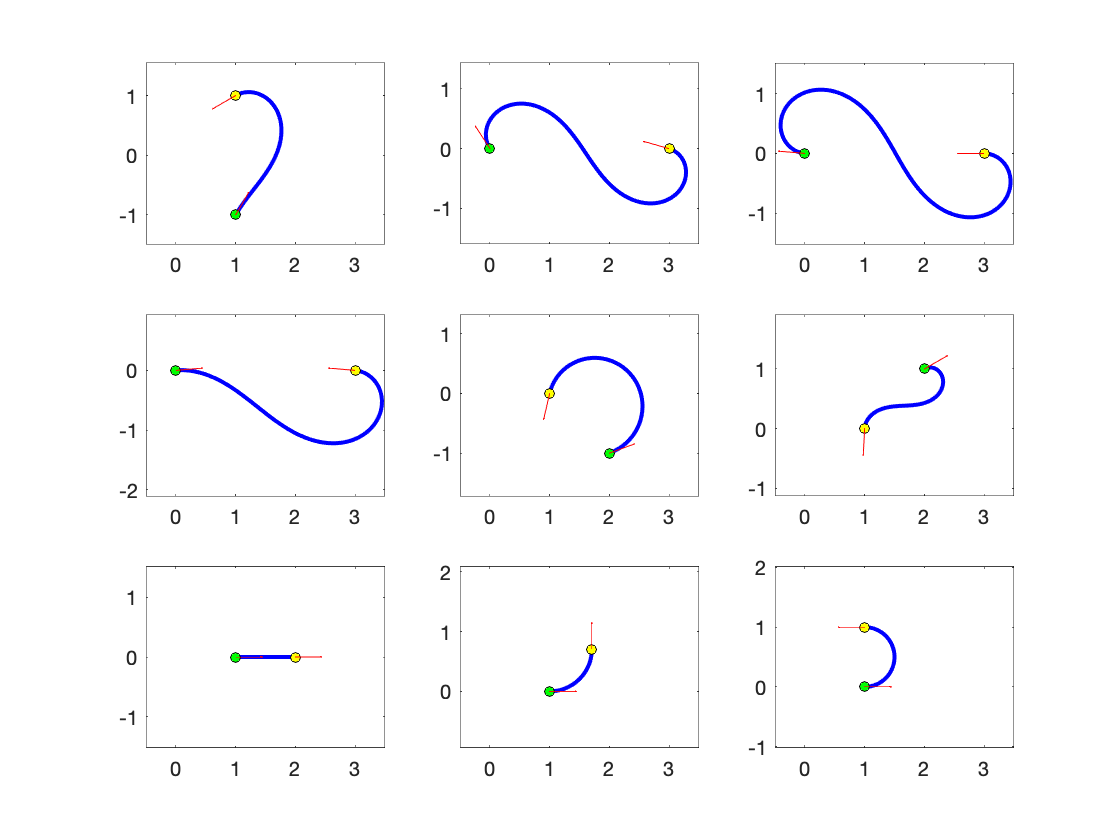

-------------------
TEST N.9


Error initial point 0 0


Error final point   0 0


Iterations 1


close all;

% test 1
tests(1).P1 = [1;-1];
tests(1).a1 = pi/3;
tests(1).P2 = [1;1];
tests(1).a2 = 7*pi/6;

% test 2
tests(2).P1 = [0;0];
tests(2).a1 = 2.14676;
tests(2).P2 = [3;0];
tests(2).a2 = 2.86234;

% test 3
tests(3).P1 = [0;0];
tests(3).a1 = 3.05433;
tests(3).P2 = [3;0];
tests(3).a2 = 3.14159;

% test 4
tests(4).P1 = [0;0];
tests(4).a1 = 0.08727;
tests(4).P2 = [3;0];
tests(4).a2 = 3.05433;

% test 5
tests(5).P1 = [2;-1];
tests(5).a1 = 0.34907;
tests(5).P2 = [1;0];
tests(5).a2 = 4.48550;

% test 6
tests(6).P1 = [2;1];
tests(6).a1 = 0.52360;
tests(6).P2 = [1;0];
tests(6).a2 = 4.66003;

% test 7
tests(7).P1 = [1;0];
tests(7).a1 = 0;
tests(7).P2 = [2;0];
tests(7).a2 = pi/10000;

% test 8
tests(8).P1 = [1;0];
tests(8).a1 = 0;
tests(8).P2 = [1+sqrt(2)/2;sqrt(2)/2];
tests(8).a2 = pi/2-1e-8;

% test 9
tests(9).P1 = [1;0];
tests(9).a1 = 0;
tests(9).P2 = [1;1];
tests(9).a2 = pi;

NPTS = 400;
LVEC = 0.5;

xmin = -0.5;
xmax =  3.5;
ymin = -1.2;
ymax =  1.2;

%for kk=1:9
C = ClothoidCurve();
for kk=1:9

  P1 = tests(kk).P1;
  a1 = tests(kk).a1;
  P2 = tests(kk).P2;
  a2 = tests(kk).a2;

  h = subplot(3,3,kk);
  set(h,'XTick',[],'YTick',[]);
  hold off;
  C = ClothoidCurve();
  iter = C.build_G1( P1(1), P1(2), a1, P2(1), P2(2), a2 );
  C.plot( 1000, '-b', 'LineWidth', 2 );
  axis ([xmin,xmax,ymin,ymax]);
  axis equal
  hold on;
  plot( P1(1), P1(2), 'ro', ...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor','g',...
        'MarkerSize',5);

  plot( P2(1), P2(2), 'bo', ...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor','y',...
        'MarkerSize',5);

  quiver( P1(1), P1(2), LVEC*cos(a1), LVEC*sin(a1), 'Color', 'r' );
  quiver( P2(1), P2(2), LVEC*cos(a2), LVEC*sin(a2), 'Color', 'r' );
    
  fprintf(1,'-------------------\nTEST N.%d\n',kk);
  [x1,y1] = C.xyBegin();
  [x2,y2] = C.xyEnd();
  fprintf(1,'Error initial point %g %g\n', [x1;y1]-P1);
  fprintf(1,'Error final point   %g %g\n', [x2;y2]-P2);
  fprintf(1,'Iterations %d\n', iter);
  
end